### Chapter 3: If you build it, they will come

Luckily, you know about the MATLAB build tool! In fact, once you take a look around you notice that there is a file called` buildfile.m` in the root of the project, and just as if you saw a `Makefile`, a `Rakefile`, a `pom.xml`, or any of these standard markers for build tools in other languages, you already know how to interact with it. Super pumped.

You know you have some test failures, so even before debugging you take a look at what build tasks the project can execute by going ot the command window and typing:

buildtool -tasks

Also, given you were running tests, the `"test"` task seems really interesting. You know that in principle a build defined in a `buildfile.m` should provide all prerequisites to any given task. You want to run tests but aren't really sure what is needed to run them? That's ok, trust the build and let the build tool do it's thing. Just go ahead and run the unit tests from the build tool:

buildtool test

You can see from here that the build tool not only ran the tests, but it also ran whatever tasks were prerequisites of running the build. Namely `mex`. Oh wait `mex` needed to run the `setupCompiler` task first? No problem. Taken care of. Note if you didn't do your homework and are on Windows you might not even have a compiler installed on your system, so this build step automatically downloads the MinGW support package for you and installs it so you can correctly compile your mex files. Isn't that build a gem?!

Alright, now that you have built enough of your project to successfully run the tests. Now go back to the quality dashboard and update the artifacts again.

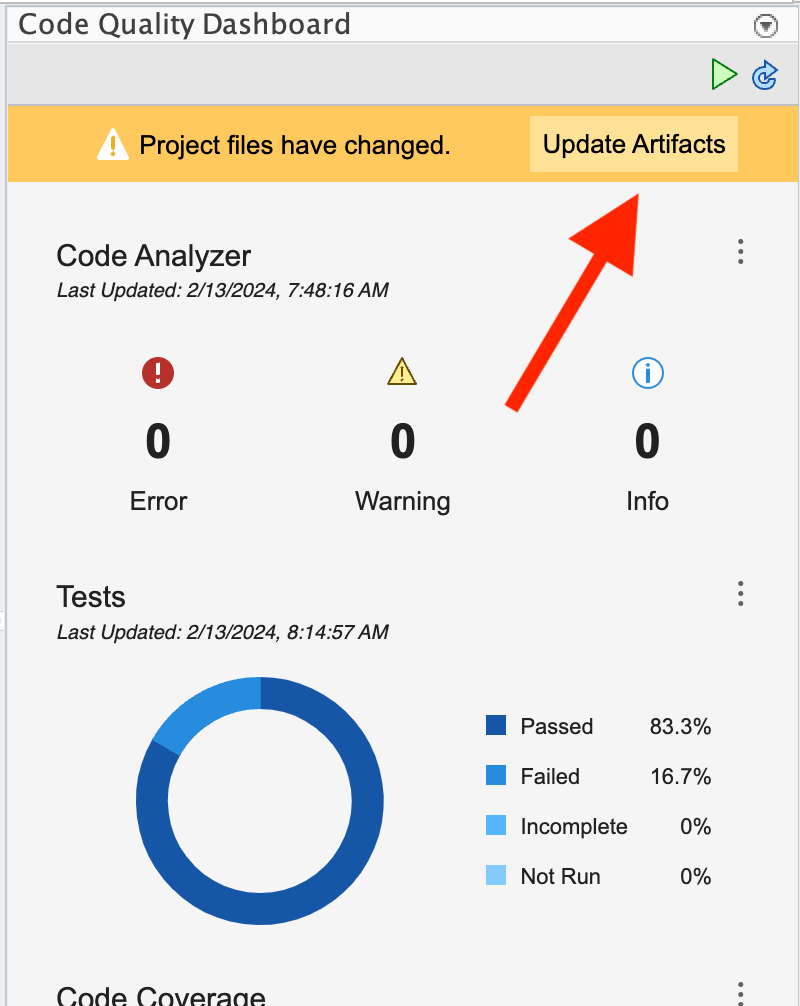

...and run the tests again to update the metric data:

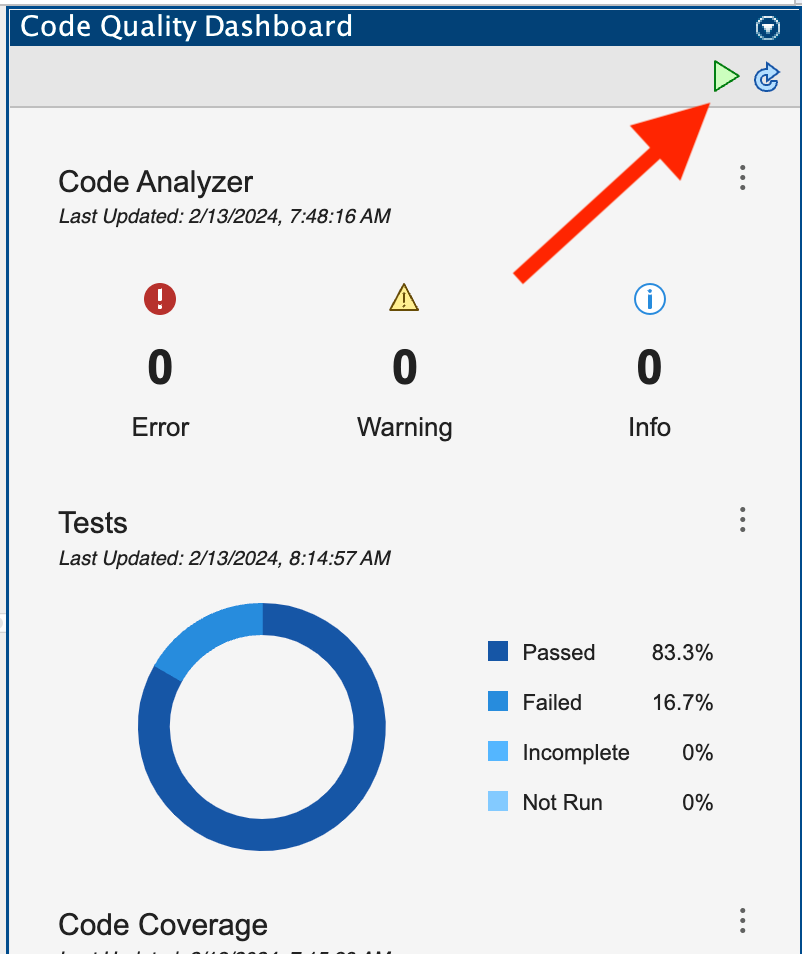

There we go. All the tests are passing. Turns out this is a pretty high quality project after all.

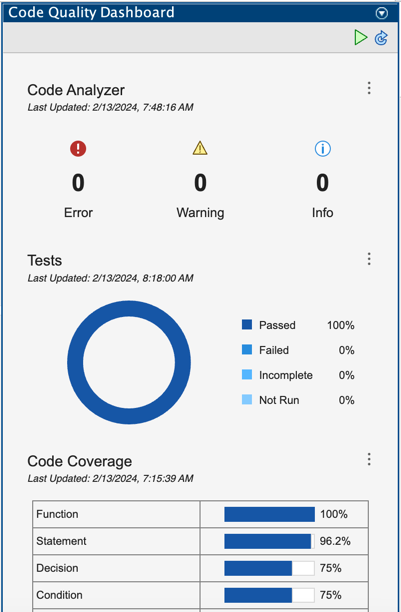

Take a look at the Code Coverage report by clicking on the card and pulling up the detailed coverage report. 

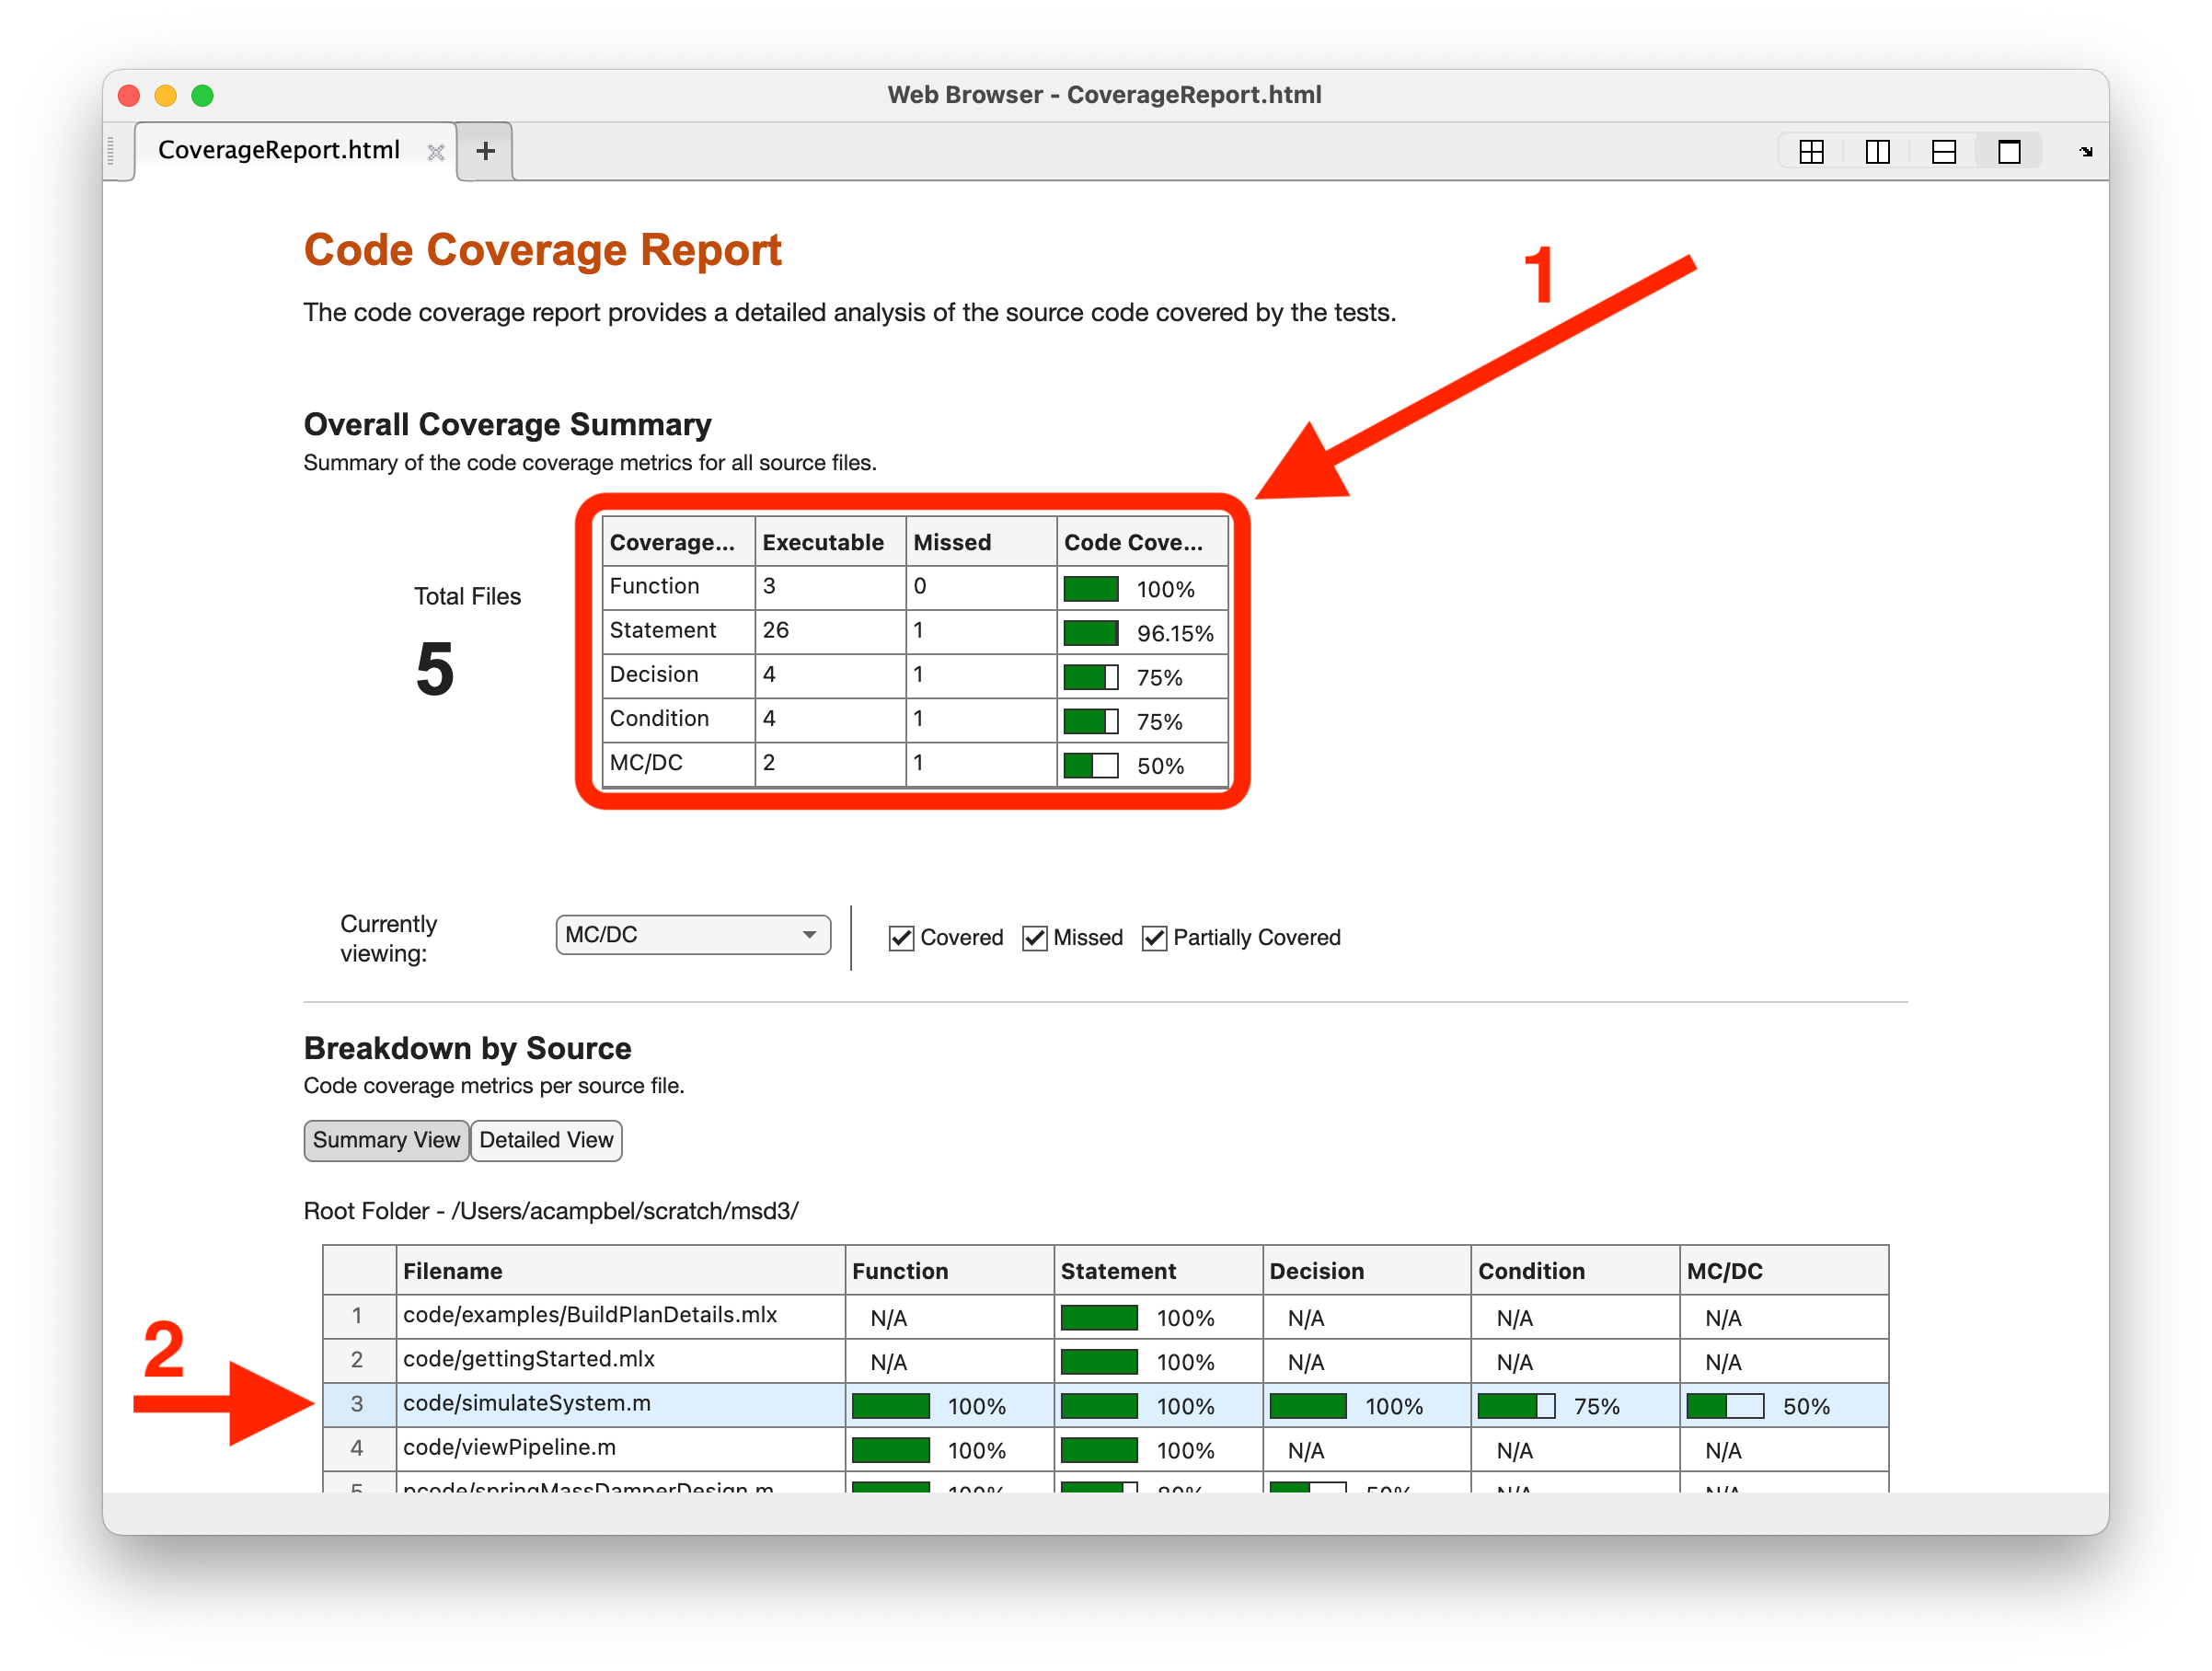

You can see that on this report there are different coverage metrics that go beyond statement coverage, which is the coverage type most people initially look for and measure. However, digging in to the coverage for a file like `simulateSystem.m`, for example, we see that this file has 100% ***Statement*** coverage, and yet ***Condition*** and ***MCDC*** metrics are pointing out the need for additional tests to fully cover the file. 

We can do that by writing a test! For the purpose of this Workshop we've already written it for you. We need another negative test so that if a user passes in an invalid struct we get the right helpful error message. Open of the test and delete line 32 to uncomment this test.

opentoline("tests/designTest.m",32)

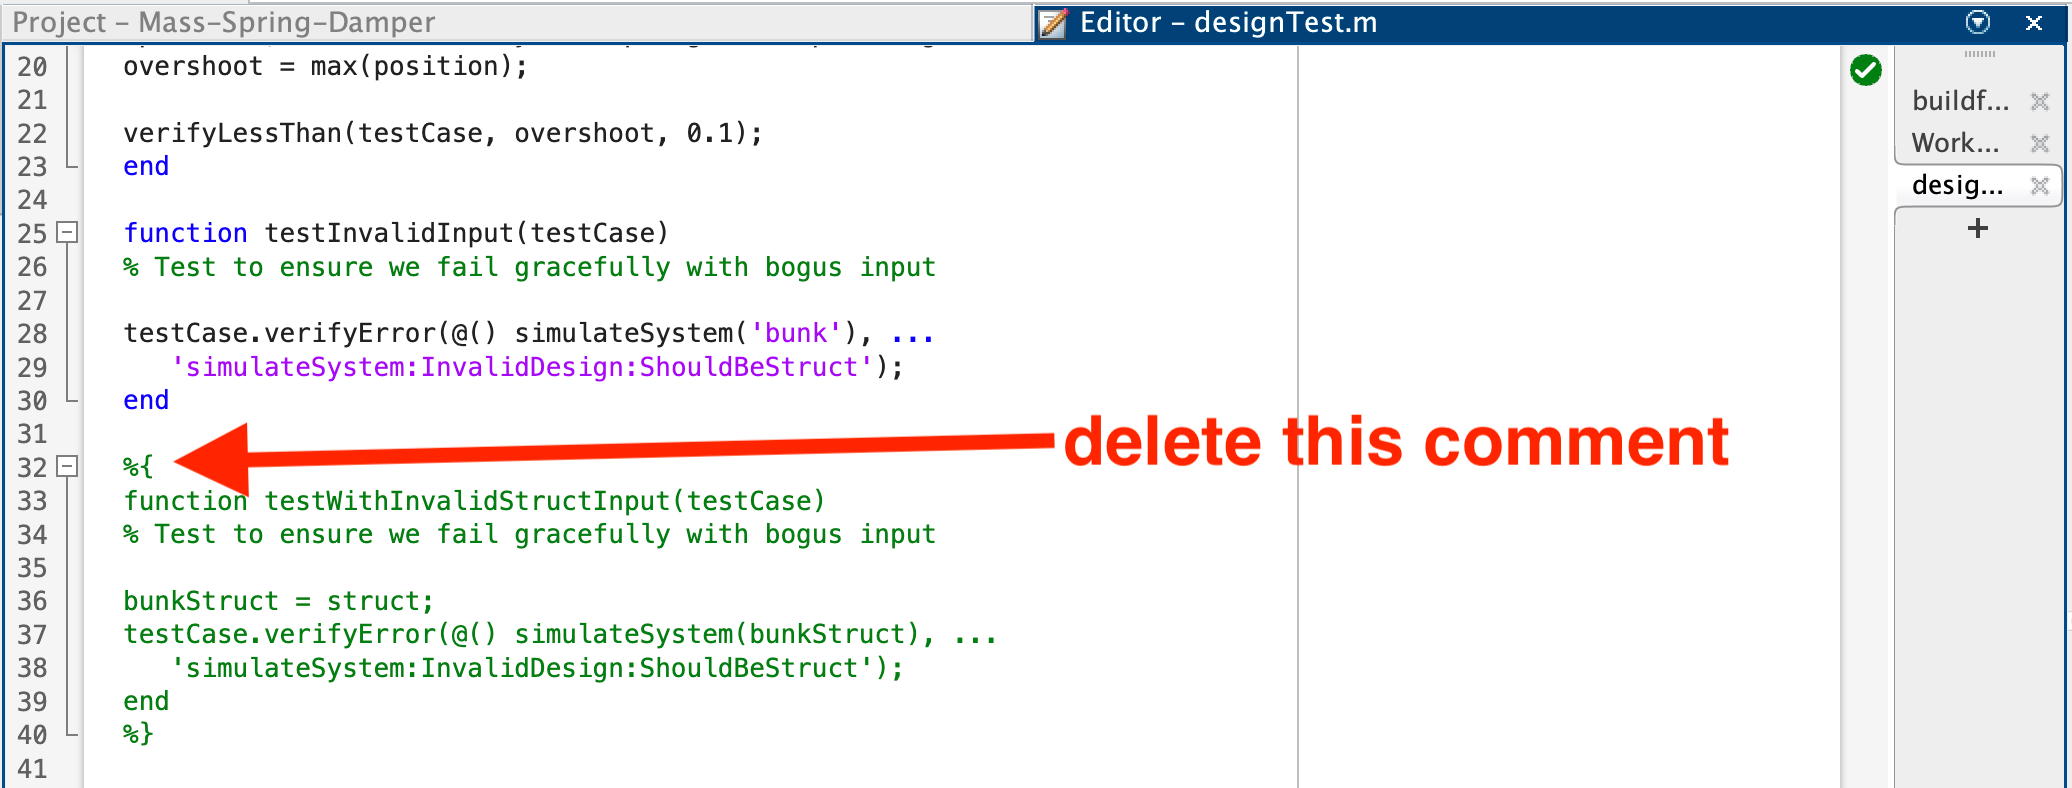

Once this test is uncommented,  again run the tests from the quality dashboard to update the metrics. 

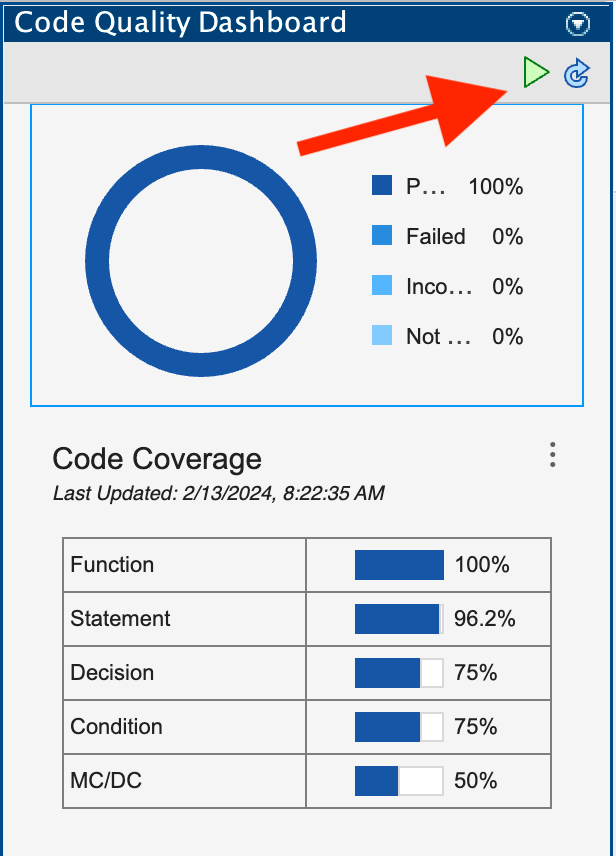

Once they are run, the quality metrics are looking in better shape

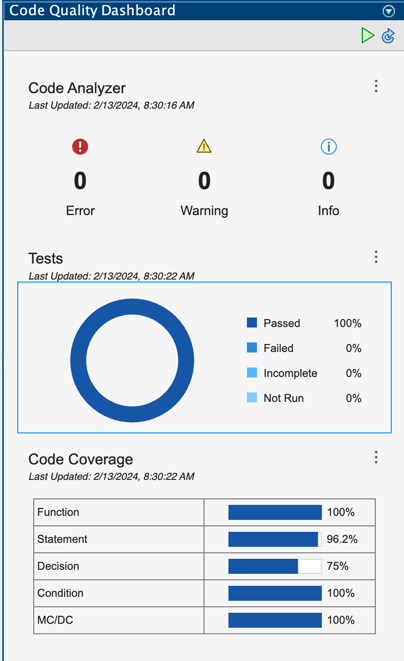

open Chapter_4

#### [Preface & TOC](matlab:open('index.html')) | [Chapter 4](matlab:open('Chapter_4.html'))